syms x y

% Exercise 1 -> No limit cycle
fx = -x + y + x^2*y

$$fx = y\,x^{2}-x+y$$

fy = 2 - y -x^2*y

$$fy = -y\,x^{2}-y+2$$

% setting the matlab function for our system
f_lmb = @(t,z) [-z(1) + 2*z(2) + (z(1))^2 * z(2);1 - 2*z(2) - (z(1)^2) * z(2)];

% 1. CALCULATE THE FIXED POINTS
fixPts = solve([fx; fy], [x; y])

fixPts = struct with fields:
    x: 2
    y: 2/5


fixPts = double([fixPts.x'; fixPts.y'])

fixPts =     2.0000
    0.4000



% Computing the jacobian matrix and the eigenvalues for the fixed points
JacFixPts = zeros(2, 2, size(fixPts, 2));
eigenvalues = zeros(size(fixPts, 2), 2);

for k = 1:size(fixPts, 2)
    JacFixPts(:,:,k) = double(subs(jacobian([fx, fy], [x, y]), {x, y}, {fixPts(1, k), fixPts(2, k)}));
    eigenvalues(k, :) = eig(JacFixPts(:,:,k));
end

% 2. IDENTIFY AND CLASSIFY THE FIXED POINTS: HYPERBOLIC VS NON-HYPERBOLIC
for k =1:size(fixPts, 2)
    if all(real(eigenvalues(k, :)) == 0)
        fprintf('Fixed point at (%f, %f) is hyperbolic.\n', fixPts(1, k), fixPts(2, k));
    else
        fprintf('Fixed point at (%f, %f) is not hyperbolic.\n', fixPts(1, k), fixPts(2, k));
    end
end

Fixed point at (2.000000, 0.400000) is not hyperbolic.



% Represent the fixed points and the eigenvalues
h1 = figure;
hold on;
grid on;
fpts = plot(fixPts(1,:), fixPts(2,:), 'o', 'MarkerFaceColor', 'r');


% 3. COMPUTE THE NULLCLINES
xcline_x = solve(fx == 0, x);
ycline_y = solve(fy == 0, y);

% Representing the nullclines
nullX = fimplicit(fx, [-eps 5 -eps 5], 'r--', 'LineWidth', 1.5);
nullY = fimplicit(fy, [-eps 5 -eps 5], 'g--', 'LineWidth', 1.5);

% 5. REPRESENT FLOW IN A GRID 10X10
% Campo vectorial
N = 10; % tamaño de la cuadrícula
xlin = linspace(eps, 5, N);
ylin = linspace(eps, 5, N);
[Xgrid, Ygrid] = meshgrid(xlin, ylin);

fx_grid = subs(fx, [x, y], {Xgrid, Ygrid});
fy_grid = subs(fy, [x, y], {Xgrid, Ygrid});

magnitude = sqrt(fx_grid.^2 + fy_grid.^2);
fx_normalized = fx_grid ./ magnitude;
fy_normalized = fy_grid ./ magnitude;

flow = quiver(Xgrid, Ygrid, fx_normalized, fy_normalized, 'AutoScale', 'on', 'AutoScaleFactor', 0.25, 'Color', 'k');

% 6. REPRESENT THE FLOW IN THE NULLCLINES
% Compute the derivatives of the nullclines
df_xcline = diff(xcline_x, y)

$$df\_xcline = \begin{array}{l} \left(\begin{array}{c} \frac{2}{\sigma_{1}}+\frac{\sigma_{1}-1}{2\,y^{2}}\\ -\frac{2}{\sigma_{1}}-\frac{\sigma_{1}+1}{2\,y^{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{-\left(2\,y-1\right)\,\left(2\,y+1\right)} \end{array}$$

df_ycline = diff(ycline_y, x)

$$df\_ycline = -\frac{4\,x}{{\left(x^{2}+1\right)}^{2}}$$


% Evaluate the nullclines and their derivatives
xcline_points = double(subs(xcline_x, y, ylin));
ycline_points = double(subs(ycline_y, x, xlin));
dxcline_points = double(subs(df_xcline, y, ylin));
dycline_points = double(subs(df_ycline, x, xlin));

% Normalize
null_mag = sqrt(ycline_points.^2);
dxcline_norm = dxcline_points ./ null_mag;
dycline_norm = dycline_points ./ null_mag;

% Plot the flow
for k = 1:size(xcline_points, 1)
    %flow_xcline = quiver(ylin, ycline_points, dxcline_norm(k,:), zeros(size(ylin)), 'cyan')
end
flow_ycline = quiver(ylin, ycline_points, dycline_norm, zeros(size(xlin)), 'cyan');

axis([-eps 5 -eps 2.5]);
xlabel('x');
ylabel('y');
title('Campo vectorial con puntos fijos, eigenvalores y nullclines');

% 4. REPRESENT A TRAJECTORY INITIALSE AT (0.5, 0.5)
y0 =[0.5 0.5]

y0 =     0.5000    0.5000


t0 = 0.5; tf = 50;
tspam = [t0,tf];
[ts,ys] = ode45(f_lmb,tspam, y0);
traj1 = plot(ys(:,1),ys(:,2),'b-'); plot(y0(1),y0(2),'o','MarkerFaceColor','b');

% 8. REPRESENT VARIOUS A TRAJECTORIES IN THE PHASE DIAGRAM
y0 =[1 0.5]

y0 =     1.0000    0.5000


t0 = 0.5; tf = 50;
tspam = [t0,tf];
[ts,ys] = ode45(f_lmb,tspam, y0);
traj2 = plot(ys(:,1),ys(:,2),'b-'); plot(y0(1),y0(2),'o','MarkerFaceColor','b');

y0 =[1.5 2]

y0 =     1.5000    2.0000


t0 = 0.5; tf = 50;
tspam = [t0,tf];
[ts,ys] = ode45(f_lmb,tspam, y0);
traj3 = plot(ys(:,1),ys(:,2),'b-'); plot(y0(1),y0(2),'o','MarkerFaceColor','b');

y0 =[0.5 2]

y0 =     0.5000    2.0000


t0 = 0.5; tf = 50;
tspam = [t0,tf];
[ts,ys] = ode45(f_lmb,tspam, y0);
traj4 = plot(ys(:,1),ys(:,2),'b-'); plot(y0(1),y0(2),'o','MarkerFaceColor','b');

y0 =[0 1]

y0 =      0     1


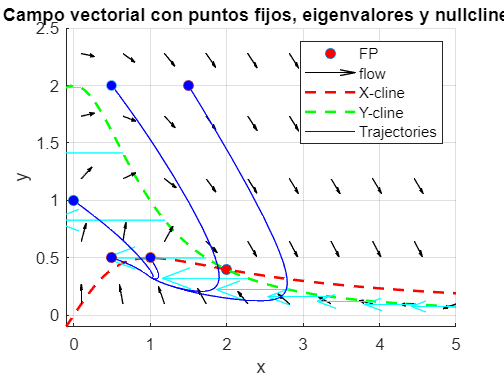

t0 = 0.5; tf = 50;
tspam = [t0,tf];
[ts,ys] = ode45(f_lmb,tspam, y0);
traj4 = plot(ys(:,1),ys(:,2),'b-'); plot(y0(1),y0(2),'o','MarkerFaceColor','b');

legend([fpts flow nullX nullY traj1],{'FP', 'flow', 'X-cline', 'Y-cline', 'Trajectories'},'Location', 'NorthEast')


disp('As it can be seen in the phase diagram, this system does not have a limit cycle')

As it can be seen in the phase diagram, this system does not have a limit cycle
